## Q2 - part c | Box-Jenkins

clc; clear;

%%

load HW5_question2

u1 = Z1.u;
y1 = Z1.y;

u2 = Z2.u;
y2 = Z2.y;

u3 = Z3.u;
y3 = Z3.y;

u1_val = u1(601:end);
y1_val = y1(601:end);

u2_val = u2(601:end);
y2_val = y2(601:end);

u3_val = u1(601:end);
y3_val = y1(601:end);

u1 = u1(1:600);
y1 = y1(1:600);

u2 = u2(1:600);
y2 = y2(1:600);

u3 = u3(1:600);
y3 = y3(1:600);

### System I

%%

% System Z1 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System I Identification Begins:------------------------------\n")

>>> System I Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data1 = iddata(y1,u1,Ts);


%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd;
    
    try
        sys = bj(data1, [na nb nc nd nk]);
        bj_y_hat_1 = lsim(sys, u1, t);
    catch
        break
    end

    [r2_bj, mse_bj] = rSQR(y1, bj_y_hat_1);

    error = y1 - bj_y_hat_1;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_bj, mse_bj, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.591082 | MSE=34.216505 | var=34.446146 | s_hat=20529.903249 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.341848 | MSE=55.071329 | var=55.815536 | s_hat=33042.797441 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.920162 | MSE=6.680476 | var=6.816813 | s_hat=4008.285760 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.920367 | MSE=6.663308 | var=6.845864 | s_hat=3997.984774 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.921021 | MSE=6.608597 | var=6.836480 | s_hat=3965.158188 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.920993 | MSE=6.610926 | var=6.886381 | s_hat=3966.555733 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.923192 | MSE=6.426930 | var=6.741535 | s_hat=3856.158046 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.601874 | MSE=33.313431 | var=35.190244 | s_hat=19988.058631 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.924425 | MSE=6.323756 | var=6.727400 | s_hat=3794.253827 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.923373 | MSE=6.411778 | var=6.869762 | s_hat=3847.066502 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=-34.614850 | MSE=2980.097149 | var=3215.932175 | s_hat=1788058.289177 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.911788 | MSE=7.381227 | var=8.023073 | s_hat=4428.736316 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.918027 | MSE=6.859154 | var=7.510022 | s_hat=4115.492329 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.924936 | MSE=6.281045 | var=6.927623 | s_hat=3768.626930 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.925088 | MSE=6.268296 | var=6.964774 | s_hat=3760.977888 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.747527 | MSE=21.125842 | var=23.648330 | s_hat=12675.505042 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.876018 | MSE=10.374245 | var=11.700276 | s_hat=6224.547088 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.858171 | MSE=11.867664 | var=13.485982 | s_hat=7120.598498 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.917350 | MSE=6.915835 | var=7.918895 | s_hat=4149.501235 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.923411 | MSE=6.408676 | var=7.394626 | s_hat=3845.205347 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.924720 | MSE=6.299132 | var=7.324572 | s_hat=3779.478952 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=-1.426182 | MSE=203.012469 | var=237.905237 | s_hat=121807.481461 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.757789 | MSE=20.267145 | var=23.937573 | s_hat=12160.287013 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.925039 | MSE=6.272410 | var=7.467155 | s_hat=3763.446211 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.915767 | MSE=7.048262 | var=8.457914 | s_hat=4228.957179 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.917542 | MSE=6.899756 | var=8.346479 | s_hat=4139.853609 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.924338 | MSE=6.331056 | var=7.720801 | s_hat=3798.633886 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.925810 | MSE=6.207940 | var=7.632713 | s_hat=3724.763711 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.921637 | MSE=6.557047 | var=8.128571 | s_hat=3934.228395 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.921055 | MSE=6.605759 | var=8.257199 | s_hat=3963.455331 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.917145 | MSE=6.932962 | var=8.739027 | s_hat=4159.776994 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.881709 | MSE=9.898088 | var=12.582316 | s_hat=5938.853081 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.903091 | MSE=8.108909 | var=10.396037 | s_hat=4865.345523 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.903813 | MSE=8.048521 | var=10.407570 | s_hat=4829.112340 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.874366 | MSE=10.512479 | var=13.711929 | s_hat=6307.487473 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.909091 | MSE=7.606864 | var=10.009032 | s_hat=4564.118516 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.921978 | MSE=6.528582 | var=8.666259 | s_hat=3917.149077 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.907109 | MSE=7.772677 | var=10.409835 | s_hat=4663.606113 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.921893 | MSE=6.535669 | var=8.831985 | s_hat=3921.401408 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.880371 | MSE=10.010045 | var=13.650061 | s_hat=6006.026860 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.879101 | MSE=10.116279 | var=13.921485 | s_hat=6069.767251 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.865477 | MSE=11.256324 | var=15.633784 | s_hat=6753.794618 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.673272 | MSE=27.339216 | var=38.326004 | s_hat=16403.529525 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.923333 | MSE=6.415199 | var=9.078111 | s_hat=3849.119139 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.922452 | MSE=6.488917 | var=9.269881 | s_hat=3893.349987 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.908099 | MSE=7.689903 | var=11.091206 | s_hat=4613.941779 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.809762 | MSE=15.918259 | var=23.181931 | s_hat=9550.955572 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.689468 | MSE=25.983961 | var=38.211707 | s_hat=15590.376428 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.887206 | MSE=9.438097 | var=14.016976 | s_hat=5662.858405 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.872083 | MSE=10.703549 | var=16.055323 | s_hat=6422.129112 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.823022 | MSE=14.808775 | var=22.437538 | s_hat=8885.265152 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.886998 | MSE=9.455534 | var=14.472756 | s_hat=5673.320453 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.817106 | MSE=15.303784 | var=23.665646 | s_hat=9182.270514 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.893953 | MSE=8.873569 | var=13.864951 | s_hat=5324.141359 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.865465 | MSE=11.257305 | var=17.774692 | s_hat=6754.383072 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.858479 | MSE=11.841872 | var=18.896604 | s_hat=7105.123070 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.746200 | MSE=21.236852 | var=34.252987 | s_hat=12742.111209 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.422229 | MSE=48.345411 | var=78.824039 | s_hat=29007.246433 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.875470 | MSE=10.420152 | var=17.176075 | s_hat=6252.091204 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.837116 | MSE=13.629470 | var=22.715784 | s_hat=8177.682256 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.827458 | MSE=14.437551 | var=24.332951 | s_hat=8662.530583 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.905898 | MSE=7.874089 | var=13.421743 | s_hat=4724.453642 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.278433 | MSE=60.377646 | var=104.099389 | s_hat=36226.587454 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.729076 | MSE=22.669711 | var=39.540193 | s_hat=13601.826432 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.179707 | MSE=68.638605 | var=121.126951 | s_hat=41183.163227 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.851215 | MSE=12.449676 | var=22.231565 | s_hat=7469.805818 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 28 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
nk = 1;
p = na+nb+nc+nd;

BestFitModel_1 = bj(data1, [na nb nc nd nk])

BestFitModel_1 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                       
                                                                                                       
  B(z) = 0.7158 z^-1 + 2.263 z^-2 + 4.049 z^-3 + 5.004 z^-4 + 4.873 z^-5 + 4.06 z^-6 + 2.409 z^-7      
          - 0.1253 z^-8 - 3.374 z^-9 - 5.961 z^-10 - 7.762 z^-11 - 8.053 z^-12 - 6.631 z^-13           
          - 3.734 z^-14 - 0.9776 z^-15 + 1.37 z^-16 + 3.829 z^-17 + 4.659 z^-18 + 3.806 z^-19          
          + 2.637 z^-20 + 2.309 z^-21 + 0.8774 z^-22 - 1.03 z^-23 - 1.495 z^-24 - 0.8161 z^-25         
                                                        - 0.4307 z^-26 - 0.3146 z^-27 - 0.02747 z^-28  
                                                                                                       
                                                                                                       
  C(z) = 1 - 0.4715 z^-1 - 0.5464 z^-2 - 0.2329

BestFit_y_hat_1 = lsim(BestFitModel_1, u1_val, t_val);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 9 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 9 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd;

bj_VarModel_1 = bj(data1, [na nb nc nd nk])

bj_VarModel_1 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                       
                                                                                                       
  B(z) = 0.7606 z^-1 + 1.281 z^-2 + 1.829 z^-3 + 1.858 z^-4 + 0.7429 z^-5 + 0.03923 z^-6 - 0.7025 z^-7 
                                                                            - 0.8477 z^-8 - 0.36 z^-9  
                                                                                                       
                                                                                                       
  C(z) = 1 + 0.2544 z^-1 + 0.5877 z^-2 - 0.2172 z^-3 + 0.08048 z^-4 + 0.6841 z^-5 + 0.1994 z^          
                                                         -6 + 0.4749 z^-7 - 0.2642 z^-8 - 0.1075 z^-9  
                                                                                                       
                                                

Var_y_hat_1 = lsim(bj_VarModel_1, u1_val, t_val);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 3 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 3 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd;

bj_AICModel_1 = bj(data1, [na nb nc nd nk])

bj_AICModel_1 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.6717 z^-1 + 0.1097 z^-2 - 0.4801 z^-3                
                                                                
  C(z) = 1 - 0.6714 z^-1 - 0.184 z^-2 + 0.803 z^-3              
                                                                
  D(z) = 1 - 0.6548 z^-1 - 0.2228 z^-2 + 0.8117 z^-3            
                                                                
  F(z) = 1 - 2.637 z^-1 + 2.528 z^-2 - 0.8878 z^-3              
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=3   nc=3   nd=3   nf=3   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data1".  
Fit to estimation data: 71.99% (prediction focus)
FPE: 6.834, MSE: 6.566         

AIC_y_hat_1 = lsim(bj_AICModel_1, u1_val, t_val);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.19 as


fprintf("    Degree = %d \n", winner)

    Degree = 3 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd;

bj_FTestModel_1 = bj(data1, [na nb nc nd nk])

bj_FTestModel_1 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.6717 z^-1 + 0.1097 z^-2 - 0.4801 z^-3                
                                                                
  C(z) = 1 - 0.6714 z^-1 - 0.184 z^-2 + 0.803 z^-3              
                                                                
  D(z) = 1 - 0.6548 z^-1 - 0.2228 z^-2 + 0.8117 z^-3            
                                                                
  F(z) = 1 - 2.637 z^-1 + 2.528 z^-2 - 0.8878 z^-3              
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=3   nc=3   nd=3   nf=3   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data1".  
Fit to estimation data: 71.99% (prediction focus)
FPE: 6.834, MSE: 6.566       

FTest_y_hat_1 = lsim(bj_FTestModel_1, u1_val, t_val);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[bj_BestFit_r2_1, bj_BestFit_mse_1] = rSQR(y1_val, BestFit_y_hat_1);
[bj_Var_r2_1, bj_Var_mse_1] = rSQR(y1_val, Var_y_hat_1);
[bj_AIC_r2_1, bj_AIC_mse_1] = rSQR(y1_val, AIC_y_hat_1);
[bj_FTest_r2_1, bj_FTest_mse_1] = rSQR(y1_val, FTest_y_hat_1);


%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2_1, bj_BestFit_mse_1)

    R2 value : 0.6488   | MSE : 25.9760 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2_1, bj_Var_mse_1)

    R2 value : 0.6512   | MSE : 25.7960 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Cov_r2, bj_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2_1, bj_AIC_mse_1)

    R2 value : 0.6541   | MSE : 25.5820 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2_1, bj_FTest_mse_1)

    R2 value : 0.6541   | MSE : 25.5820 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

bj_BestFitError_1 = y1_val - BestFit_y_hat_1;
bj_VarError_1 = y1_val - Var_y_hat_1;
bj_AICError_1 = y1_val - AIC_y_hat_1;
bj_FTestError_1 = y1_val - FTest_y_hat_1;

for k=0:N_val-1
    bj_BestFit_Ree_1(k+1,1) = AutoCorrelate(bj_BestFitError_1, k);
    bj_Var_Ree_1(k+1,1) = AutoCorrelate(bj_VarError_1, k);
    bj_AIC_Ree_1(k+1,1) = AutoCorrelate(bj_AICError_1, k);
    bj_FTest_Ree_1(k+1,1) = AutoCorrelate(bj_FTestError_1, k);
end

for k=0:N_val-1
    bj_BestFit_Rue_1(k+1,1) = CrossCorrelate(u1_val, bj_BestFitError_1, k);
    bj_Var_Rue_1(k+1,1) = CrossCorrelate(u1_val, bj_VarError_1, k);
    bj_AIC_Rue_1(k+1,1) = CrossCorrelate(u1_val, bj_AICError_1, k);
    bj_FTest_Rue_1(k+1,1) = CrossCorrelate(u1_val, bj_FTestError_1, k);
end



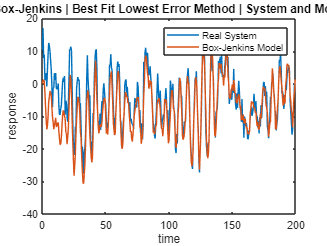

%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_1)
legend('Real System','Box-Jenkins Model')
title(" System I : Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

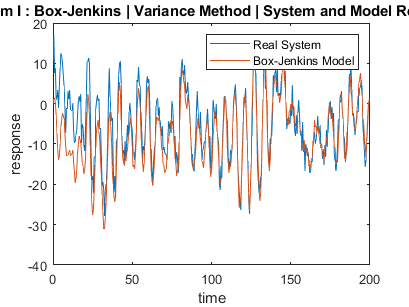


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_1)
legend('Real System','Box-Jenkins Model')
title(" System I : Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

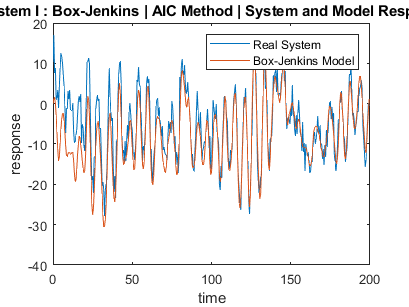


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_1)
legend('Real System','Box-Jenkins Model')
title(" System I : Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

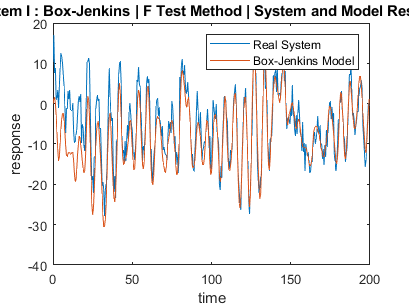


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_1)
legend('Real System','Box-Jenkins Model')
title(" System I : Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

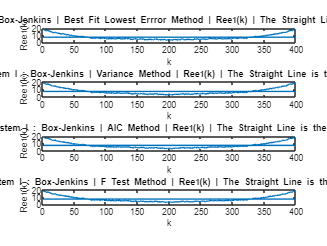

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Ree_1(2:end), 1:N_val-1, mean(bj_BestFit_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | Best Fit Lowest Errror Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Ree_1(2:end), 1:N_val-1, mean(bj_Var_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | Variance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Ree_1(2:end), 1:N_val-1, mean(bj_AIC_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | AIC Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Ree_1(2:end), 1:N_val-1, mean(bj_FTest_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | F Test Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

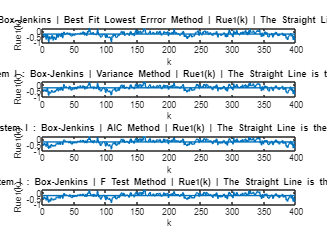

%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Rue_1(2:end), 1:N_val-1, mean(bj_BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Rue_1(2:end), 1:N_val-1, mean(bj_Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Rue_1(2:end), 1:N_val-1, mean(bj_AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Rue_1(2:end), 1:N_val-1, mean(bj_FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Box-Jenkins | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

### System II

%%

% System Z2 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System II Identification Begins:------------------------------\n")

>>> System II Identification Begins:------------------------------


%%


Ts = 0.5; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data2 = iddata(y2,u2,Ts);



%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd;
    
    try
        sys = bj(data2, [na nb nc nd nk]);
        bj_y_hat_2 = lsim(sys, u2, t);
    catch
        break
    end

    [r2_bj, mse_bj] = rSQR(y2, bj_y_hat_2);

    error = y2 - bj_y_hat_2;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_bj, mse_bj, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.316984 | MSE=51.227536 | var=51.571345 | s_hat=30736.521790 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.670196 | MSE=24.735937 | var=25.070206 | s_hat=14841.561905 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.670189 | MSE=24.736482 | var=25.241309 | s_hat=14841.889456 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=-2.964854 | MSE=297.371626 | var=305.518794 | s_hat=178422.975463 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=-2404087.135744 | MSE=180311194.315684 | var=186528821.705880 | s_hat=108186716589.410446 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=-134144.819268 | MSE=10061192.235438 | var=10480408.578581 | s_hat=6036715341.262638 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=-10206457.069827 | MSE=765503816.994763 | var=802976031.812690 | s_hat=459302290196.858459 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=-45442419.284294 | MSE=3408268171.300644 | var=3600283279.542933 | s_hat=2044960902780.386230 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=-2657627.411681 | MSE=199327198.463634 | var=212050211.131525 | s_hat=119596319078.180252 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=-27049849.524714 | MSE=2028790368.229715 | var=2173703965.960406 | s_hat=1217274220937.827393 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=-22150322.810308 | MSE=1661316522.191645 | var=1792787613.875875 | s_hat=996789913314.986816 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=-7529824.670283 | MSE=564751283.204409 | var=613860090.439575 | s_hat=338850769922.645447 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=-166775936.024440 | MSE=12508513286.553482 | var=13695452503.525702 | s_hat=7505107971932.083984 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=-20085999.115661 | MSE=1506488308.823869 | var=1661567987.673385 | s_hat=903892985294.321655 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=-40502182.412845 | MSE=3037740985.857914 | var=3375267762.064350 | s_hat=1822644591514.748779 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=-6840.385899 | MSE=513116.987671 | var=574384.687691 | s_hat=307870192.602618 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=-14061208.116257 | MSE=1054617495.747789 | var=1189418228.286980 | s_hat=632770497448.673218 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=-366232190.241741 | MSE=27468112677.667683 | var=31213764406.440552 | s_hat=16480867606600.611328 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=-421987756.729301 | MSE=31649886479.404797 | var=36240328029.852821 | s_hat=18989931887642.878906 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=-3624661.252297 | MSE=271856580.457921 | var=313680669.759140 | s_hat=163113948274.752960 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=-21763574207.956158 | MSE=1632309564632.983398 | var=1898034377480.210938 | s_hat=979385738779788.875000 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=-23387245.862201 | MSE=1754088109.658652 | var=2055572003.506239 | s_hat=1052452865795.194214 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.623785 | MSE=28.216859 | var=33.326998 | s_hat=16930.115158 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=-2593714.639835 | MSE=194533618.705853 | var=231587641.316492 | s_hat=116720171223.512039 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=-12871812.625668 | MSE=965410566.004599 | var=1158492679.205521 | s_hat=579246339602.760498 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=-424554134.236771 | MSE=31842369686.054630 | var=38518995587.969269 | s_hat=19105421811632.757812 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=-7692975.690453 | MSE=576987920.814818 | var=703643805.871730 | s_hat=346192752488.891052 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=-23279.726999 | MSE=1746098.916788 | var=2146842.930477 | s_hat=1047659350.072673 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=-2698299.129616 | MSE=202377654.861963 | var=250881390.324747 | s_hat=121426592917.177521 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=-962312691.729610 | MSE=72175286900.432465 | var=90219108625.540771 | s_hat=43305172140259.570312 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=-104964153.893176 | MSE=7872511763.497084 | var=9923334155.668591 | s_hat=4723507058098.249023 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.443474 | MSE=41.740527 | var=53.059992 | s_hat=25044.316108 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=-15204554.634723 | MSE=1140370664.775239 | var=1462013672.788769 | s_hat=684222398865.144043 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=-6402088.486479 | MSE=480168919.042541 | var=620908084.968803 | s_hat=288101351425.524536 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=-1735552812.821838 | MSE=130169770402.935593 | var=169786657047.306885 | s_hat=78101862241761.171875 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=-61623112.870496 | MSE=4621851043.744657 | var=6081382952.295606 | s_hat=2773110626246.796387 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=-33914237.169555 | MSE=2543632530.663309 | var=3376503359.287581 | s_hat=1526179518397.986816 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=-13359549.401789 | MSE=1001991754.234143 | var=1341953242.277871 | s_hat=601195052540.486328 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=-6804.446995 | MSE=510421.501323 | var=689758.785572 | s_hat=306252900.793943 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=-2467622.734707 | MSE=185076485.388156 | var=252377025.529304 | s_hat=111045891232.893875 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=-10230189.785375 | MSE=767283815.914534 | var=1055895159.515412 | s_hat=460370289548.719604 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=-502932.331958 | MSE=37720958.894221 | var=52390220.686418 | s_hat=22632575336.532646 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=-3656788.435578 | MSE=274266180.464344 | var=384485299.716370 | s_hat=164559708278.606232 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=-7322629.024973 | MSE=549211214.723805 | var=777185681.212932 | s_hat=329526728834.283020 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=-407603.256928 | MSE=30571096.492712 | var=43672994.989588 | s_hat=18342657895.627014 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=-2879246.054555 | MSE=215949019.263421 | var=311464931.629934 | s_hat=129569411558.052597 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=-1622266.274091 | MSE=121673138.909303 | var=177193891.615490 | s_hat=73003883345.582047 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=-12840933.331805 | MSE=963094560.083949 | var=1416315529.535217 | s_hat=577856736050.368652 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=-4896530.194347 | MSE=367249176.321765 | var=545419568.794700 | s_hat=220349505793.058777 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=-19942.388250 | MSE=1495792.146934 | var=2243688.220401 | s_hat=897475288.160488 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=-517453.297313 | MSE=38810058.984590 | var=58803119.673621 | s_hat=23286035390.753868 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=-126818.843302 | MSE=9511730.068792 | var=14558770.513457 | s_hat=5707038041.275229 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=-620051.986916 | MSE=46505156.340826 | var=71915190.217773 | s_hat=27903093804.495842 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-8738.746470 | MSE=655497.650271 | var=1024215.078549 | s_hat=393298590.162778 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=-382798.063865 | MSE=28710659.714245 | var=45332620.601440 | s_hat=17226395828.547054 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=-4012990.550389 | MSE=300982018.284271 | var=480290454.708943 | s_hat=180589210970.562683 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-771117.532600 | MSE=57835360.320113 | var=93282839.225989 | s_hat=34701216192.068069 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=-15742380.753726 | MSE=1180708649.231739 | var=1925068449.834358 | s_hat=708425189539.043579 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=-1242562.183432 | MSE=93194608.087067 | var=153617485.857803 | s_hat=55916764852.240349 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=-5824616.123262 | MSE=436857390.672224 | var=728095651.120372 | s_hat=262114434403.333862 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=-15913.570364 | MSE=1193623.123319 | var=2011724.365145 | s_hat=716173873.991554 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=-1053344.519552 | MSE=79002922.494223 | var=134664072.433334 | s_hat=47401753496.533524 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=-11394203.154396 | MSE=854587038.141365 | var=1473425927.829938 | s_hat=512752222884.818298 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=-258008.145218 | MSE=19351177.865294 | var=33752054.416211 | s_hat=11610706719.176493 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 2 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
nk = 1;
p = na+nb+nc+nd;

BestFitModel_2 = bj(data2, [na nb nc nd nk])

BestFitModel_2 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = -0.4335 z^-1 + 1.698 z^-2                              
                                                                
  C(z) = 1 + 0.4345 z^-1 - 0.5655 z^-2                          
                                                                
  D(z) = 1 + 0.3866 z^-1 - 0.5945 z^-2                          
                                                                
  F(z) = 1 - 1.64 z^-1 + 0.8852 z^-2                            
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data2".  
Fit to estimation data: 42.82% (prediction focus)
FPE: 25.19, MSE: 24.53         

BestFit_y_hat_2 = lsim(BestFitModel_2, u2_val, t_val);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 2 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 2 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd;

bj_VarModel_2 = bj(data2, [na nb nc nd nk])

bj_VarModel_2 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = -0.4335 z^-1 + 1.698 z^-2                              
                                                                
  C(z) = 1 + 0.4345 z^-1 - 0.5655 z^-2                          
                                                                
  D(z) = 1 + 0.3866 z^-1 - 0.5945 z^-2                          
                                                                
  F(z) = 1 - 1.64 z^-1 + 0.8852 z^-2                            
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data2".  
Fit to estimation data: 42.82% (prediction focus)
FPE: 25.19, MSE: 24.53          

Var_y_hat_2 = lsim(bj_VarModel_2, u2_val, t_val);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd;



bj_AICModel_2 = bj(data2, [na nb nc nd nk])

bj_AICModel_2 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = -0.4335 z^-1 + 1.698 z^-2                              
                                                                
  C(z) = 1 + 0.4345 z^-1 - 0.5655 z^-2                          
                                                                
  D(z) = 1 + 0.3866 z^-1 - 0.5945 z^-2                          
                                                                
  F(z) = 1 - 1.64 z^-1 + 0.8852 z^-2                            
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data2".  
Fit to estimation data: 42.82% (prediction focus)
FPE: 25.19, MSE: 24.53          

AIC_y_hat_2 = lsim(bj_AICModel_2, u2_val, t_val);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.19 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd;

bj_FTestModel_2 = bj(data2, [na nb nc nd nk])

bj_FTestModel_2 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = -0.4335 z^-1 + 1.698 z^-2                              
                                                                
  C(z) = 1 + 0.4345 z^-1 - 0.5655 z^-2                          
                                                                
  D(z) = 1 + 0.3866 z^-1 - 0.5945 z^-2                          
                                                                
  F(z) = 1 - 1.64 z^-1 + 0.8852 z^-2                            
                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data2".  
Fit to estimation data: 42.82% (prediction focus)
FPE: 25.19, MSE: 24.53        

FTest_y_hat_2 = lsim(bj_FTestModel_2, u2_val, t_val);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[bj_BestFit_r2_2, bj_BestFit_mse_2] = rSQR(y2_val, BestFit_y_hat_2);
[bj_Var_r2_2, bj_Var_mse_2] = rSQR(y2_val, Var_y_hat_2);
[bj_AIC_r2_2, bj_AIC_mse_2] = rSQR(y2_val, AIC_y_hat_2);
[bj_FTest_r2_2, bj_FTest_mse_2] = rSQR(y2_val, FTest_y_hat_2);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2_2, bj_BestFit_mse_2)

    R2 value : 0.7021   | MSE : 26.3189 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2_2, bj_Var_mse_2)

    R2 value : 0.7021   | MSE : 26.3189 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Cov_r2, bj_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2_2, bj_AIC_mse_2)

    R2 value : 0.7021   | MSE : 26.3189 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2_2, bj_FTest_mse_2)

    R2 value : 0.7021   | MSE : 26.3189 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")



%%

bj_BestFitError_2 = y2_val - BestFit_y_hat_2;
bj_VarError_2 = y2_val - Var_y_hat_2;
bj_AICError_2 = y2_val - AIC_y_hat_2;
bj_FTestError_2 = y2_val - FTest_y_hat_2;

for k=0:N_val-1
    bj_BestFit_Ree_2(k+1,1) = AutoCorrelate(bj_BestFitError_2, k);
    bj_Var_Ree_2(k+1,1) = AutoCorrelate(bj_VarError_2, k);
    bj_AIC_Ree_2(k+1,1) = AutoCorrelate(bj_AICError_2, k);
    bj_FTest_Ree_2(k+1,1) = AutoCorrelate(bj_FTestError_2, k);
end

for k=0:N_val-1
    bj_BestFit_Rue_2(k+1,1) = CrossCorrelate(u2_val, bj_BestFitError_2, k);
    bj_Var_Rue_2(k+1,1) = CrossCorrelate(u2_val, bj_VarError_2, k);
    bj_AIC_Rue_2(k+1,1) = CrossCorrelate(u2_val, bj_AICError_2, k);
    bj_FTest_Rue_2(k+1,1) = CrossCorrelate(u2_val, bj_FTestError_2, k);
end

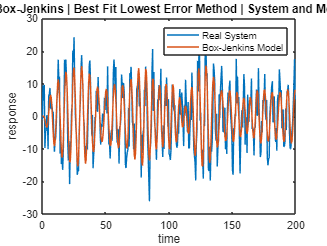



%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_2)
legend('Real System','Box-Jenkins Model')
title(" System II : Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

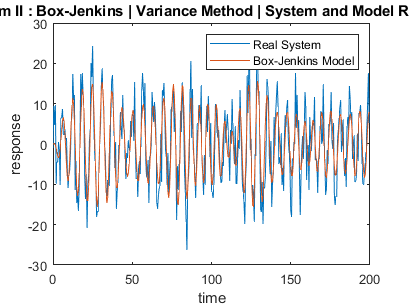


figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_2)
legend('Real System','Box-Jenkins Model')
title(" System II : Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

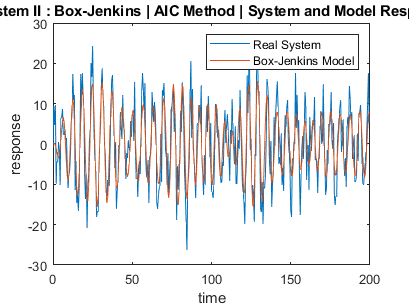


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_2)
legend('Real System','Box-Jenkins Model')
title(" System II : Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

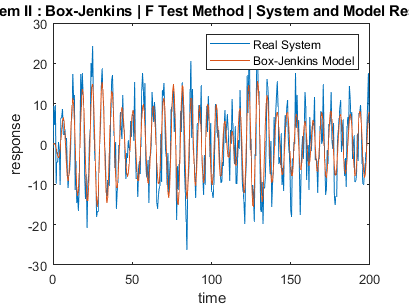


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_2)
legend('Real System','Box-Jenkins Model')
title(" System II : Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

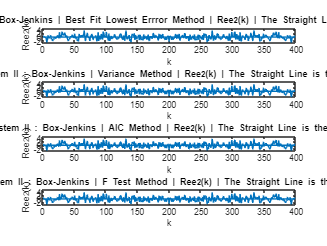


%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Ree_2(2:end), 1:N_val-1, mean(bj_BestFit_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | Best Fit Lowest Errror Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Ree_2(2:end), 1:N_val-1, mean(bj_Var_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | Variance Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Ree_2(2:end), 1:N_val-1, mean(bj_AIC_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | AIC Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Ree_2(2:end), 1:N_val-1, mean(bj_FTest_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | F Test Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

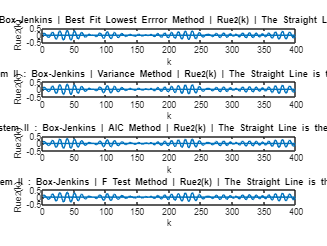


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Rue_2(2:end), 1:N_val-1, mean(bj_BestFit_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | Best Fit Lowest Errror Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Rue_2(2:end), 1:N_val-1, mean(bj_Var_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | Variance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Rue_2(2:end), 1:N_val-1, mean(bj_AIC_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | AIC Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Rue_2(2:end), 1:N_val-1, mean(bj_FTest_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Box-Jenkins | F Test Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")